# IQ Demodulator Test

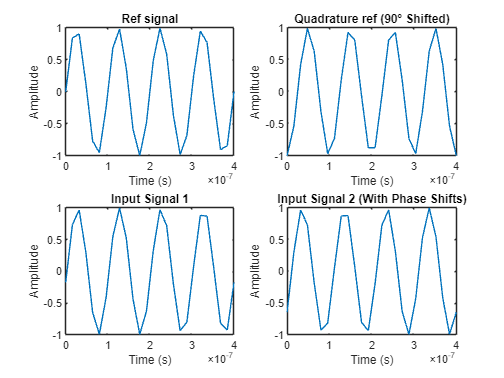

clc
clear all
close all

% Medfrekvenca
FREQUENCY = 10e6;
SAMPLE_RATE = 62.5e6;
SAMPLE_COUNT = 4096;

% Za grafe
DISPLAY_PERIODS = 4;
DISPLAY_PERIODS_LONG = 40;

% Parametri zamika vhodnih signalov
COMMON_PHASE_SHIFT_DEG = 10;
ADDITIONAL_PHASE_SHIFT_DEG = 30;

% Sliding window average za lowpass
WINDOW_SIZE = 100;

% Degrees to radians
COMMON_PHASE_SHIFT = deg2rad(COMMON_PHASE_SHIFT_DEG);
ADDITIONAL_PHASE_SHIFT = deg2rad(ADDITIONAL_PHASE_SHIFT_DEG);

% Časovni vektor
t = (0:SAMPLE_COUNT-1) / SAMPLE_RATE;

% 10 MHz base signal
lo = sin(2*pi*FREQUENCY*t);

% 90° quadrature base signal
lo90 = sin(2*pi*FREQUENCY*t - deg2rad(90));

% Vhodna signala (referenca, zamaknjen)
in_ref = sin(2*pi*FREQUENCY*t - COMMON_PHASE_SHIFT);
in_test = sin(2*pi*FREQUENCY*t - COMMON_PHASE_SHIFT - ADDITIONAL_PHASE_SHIFT);

% Za omejevanje signala
period = 1/FREQUENCY;
display_time = DISPLAY_PERIODS * period;
display_indices = t <= display_time;

figure;
subplot(2,2,1);
plot(t, lo);
title('Ref signal');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 display_time]);

subplot(2,2,2);
plot(t, lo90);
title('Quadrature ref (90° Shifted)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 display_time]);

subplot(2,2,3);
plot(t, in_ref);
title('Input Signal 1');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 display_time]);

subplot(2,2,4);
plot(t, in_test);
title('Input Signal 2 (With Phase Shifts)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 display_time]);

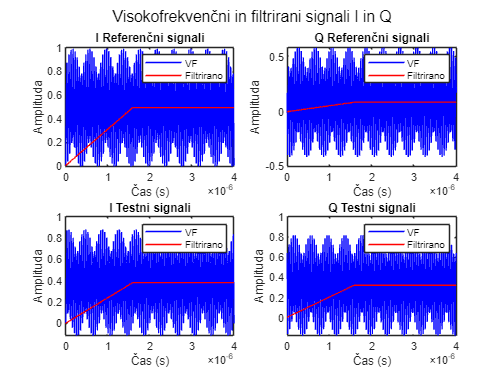

I_hf_ref = in_ref .* lo;
Q_hf_ref = in_ref .* lo90;
I_hf_test = in_test .* lo;
Q_hf_test = in_test .* lo90;

b = (1/WINDOW_SIZE) * ones(1, WINDOW_SIZE);
a = 1;

% Filtriranje signalov
I_ref = filter(b, a, I_hf_ref);
Q_ref = filter(b, a, Q_hf_ref);
I_test = filter(b, a, I_hf_test);
Q_test = filter(b, a, Q_hf_test);

% Omejevanje
display_time_long = DISPLAY_PERIODS_LONG * period;
display_indices_long = t <= display_time_long;

figure;

% I Referenca
subplot(2,2,1);
plot(t, I_hf_ref, 'b');
hold on;
plot(t, I_ref, 'r');
title('I Referenčni signali');
xlabel('Čas (s)');
ylabel('Amplituda');
xlim([0 display_time_long]);
legend('VF', 'Filtrirano');

% Q Referenca
subplot(2,2,2);
plot(t, Q_hf_ref, 'b');
hold on;
plot(t, Q_ref, 'r');
title('Q Referenčni signali');
xlabel('Čas (s)');
ylabel('Amplituda');
xlim([0 display_time_long]);
legend('VF', 'Filtrirano');

% I Test
subplot(2,2,3);
plot(t, I_hf_test, 'b');
hold on;
plot(t, I_test, 'r');
title('I Testni signali');
xlabel('Čas (s)');
ylabel('Amplituda');
xlim([0 display_time_long]);
legend('VF', 'Filtrirano');

% Q Test
subplot(2,2,4);
plot(t, Q_hf_test, 'b');
hold on;
plot(t, Q_test, 'r');
title('Q Testni signali');
xlabel('Čas (s)');
ylabel('Amplituda');
xlim([0 display_time_long]);
legend('VF', 'Filtrirano');

sgtitle('Visokofrekvenčni in filtrirani signali I in Q');

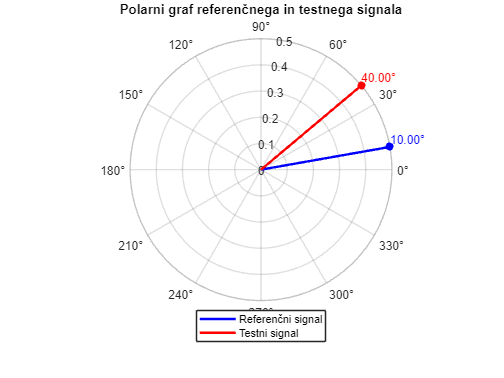

% Končne IQ vrednosti
final_I_ref = I_ref(end);
final_Q_ref = Q_ref(end);
final_I_test = I_test(end);
final_Q_test = Q_test(end);

% Izračun amplitud in faz
mag_ref = sqrt(final_I_ref^2 + final_Q_ref^2);
angle_ref = atan2(final_Q_ref, final_I_ref);
mag_test = sqrt(final_I_test^2 + final_Q_test^2);
angle_test = atan2(final_Q_test, final_I_test);

figure;
polarplot([0 angle_ref], [0 mag_ref], 'b', 'LineWidth', 2);
hold on;
polarplot([0 angle_test], [0 mag_test], 'r', 'LineWidth', 2);

polarplot(angle_ref, mag_ref, 'b.', 'MarkerSize', 20);
polarplot(angle_test, mag_test, 'r.', 'MarkerSize', 20);

% Dodajanje dejanskih vrednosti kota v stopinjah
text(angle_ref, mag_ref, sprintf('%.2f°', rad2deg(angle_ref)), 'Color', 'blue', ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
text(angle_test, mag_test, sprintf('%.2f°', rad2deg(angle_test)), 'Color', 'red', ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');

legend('Referenčni signal', 'Testni signal', 'Location', 'southoutside');
title('Polarni graf referenčnega in testnega signala');


fprintf('Referenčni signal - Amplituda: %.3f, Kot: %.2f stopinj\n', ...
    mag_ref, rad2deg(angle_ref));

Referenčni signal - Amplituda: 0.500, Kot: 10.00 stopinj


fprintf('Testni signal - Amplituda: %.3f, Kot: %.2f stopinj\n', ...
    mag_test, rad2deg(angle_test));

Testni signal - Amplituda: 0.500, Kot: 40.00 stopinj



phase_diff = rad2deg(mod(angle_test - angle_ref, 2*pi));
fprintf('Fazna razlika: %.2f stopinj\n', phase_diff);

Fazna razlika: 30.00 stopinj
